# Here we will work on a robot arm

% Describing a robot arm
% Arms are made of links connected by joints

% A link is created using the toolbox by:
L = Link([0, 0.1, 0.2, pi/2, 0]) % The values are the link parameters in the DH table. [θj, dj, aj, αj] in that order

 
L = 
Revolute(std): theta=q, d=0.1, a=0.2, alpha=1.5708, offset=0


% Link transformation for angle theta as 0.5 radians is:
L.A(0.5)

 

ans = 
    0.8776         0    0.4794    0.1755
    0.4794         0   -0.8776   0.09589
         0         1         0       0.1
         0         0         0         1


% To set the link offset:
% L.offset = 0.5;


## Robot Construction

% To create a robot, we use the DH table. We will use this as an example:

The robot below will be modelled:

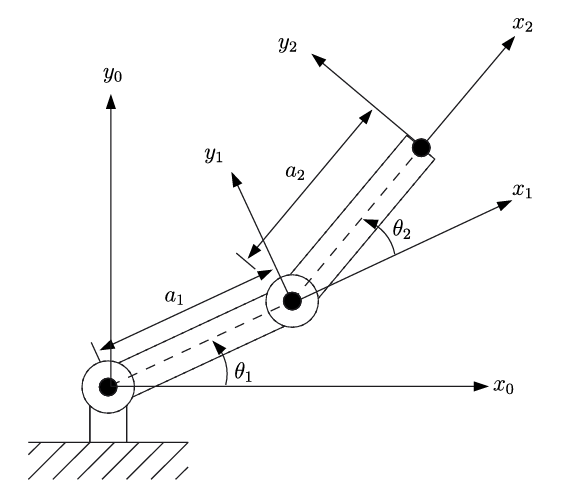

The DH Table is given below

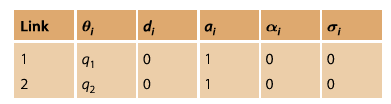

% Concise robot description
L(1) = Link([0 0 1 0]);
L(2) = Link([0 0 1 0]);
two_link_bot = SerialLink(L, 'name', 'wkk_bot');
two_link_bot

 
two_link_bot = 
 
wkk_bot:: 2 axis, RR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Kinematics

### Forward Kinematics

% The forward kinmeatic of the robot can be computed as:
two_link_bot.fkine([0,0]); % -> This is the case where q1 and q2 are zero. q is angle theta

% We can orient the base as we want
%two_link_bot.base = transl(-2,-2,0) * trotx(pi);

% To graphically visualize the robot:
two_link_bot.plot([pi/5 pi/3])

### Inverse Kinematics

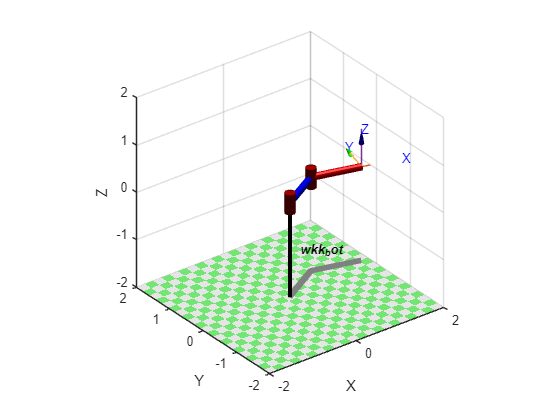

T = transl2(0.4, 0.5);
two_link_bot.plot([pi/6, -pi/4])

% The inverse kinematic is computed using a numerical solution
two_link_bot.ikine(T, [0 0], [1 1 0 0 0 0])

Error using SE3.convert (line 955)
expecting an SE3 or 4x4 matrix

Error in SerialLink/ikine (line 112)
    TT = SE3.convert(tr);